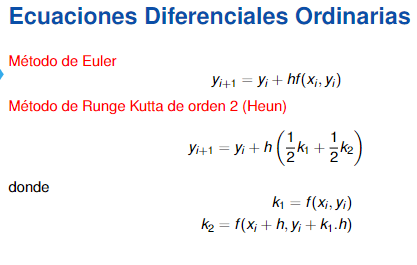

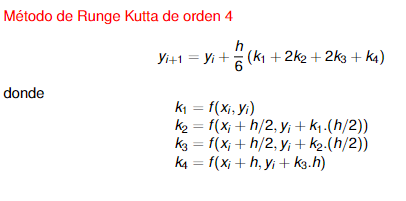

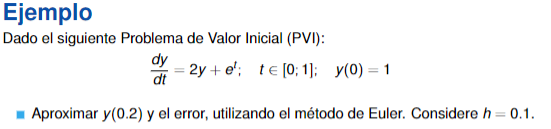

f=@(t,y)(2*y+exp(t))

f = function_handle with value:
    @(t,y)(2*y+exp(t))


syms y(t) t
y(t)=dsolve(diff(y,t)==2*y+exp(t),y(0)==1)

$$y(t) = 2\,{\mathrm{e}}^{2\,t}-{\mathrm{e}}^{t}$$

SolEx=inline(subs(y(t)),'t')

SolEx =

     Inline function:
     SolEx(t) = exp(t.*2.0).*2.0-exp(t)



y0=1; h=0.1; a=0; b=1; t=[a:h:b]';
z=[t(1) y0 SolEx(t(1)) abs(SolEx(t(1))-y0) ]

z =      0     1     1     0


y1=y0+h*f(t(1),y0);
z=[z;t(2) y1 SolEx(t(2)) abs(SolEx(t(2))-y1)]

z =          0    1.0000    1.0000         0
    0.1000    1.3000    1.3376    0.0376


y2=y1+h*f(t(2),y1);
z=[z;t(3) y2 SolEx(t(3)) abs(SolEx(t(3))-y2)]

z =          0    1.0000    1.0000         0
    0.1000    1.3000    1.3376    0.0376
    0.2000    1.6705    1.7622    0.0917


f=@(t,y)(2*y+exp(t))
syms y(t) t
y(t)=dsolve(diff(y,t)==2*y+exp(t),y(0)==1)
SolEx=inline(subs(y(t)),'t')
y0=1; h=0.1; a=0; b=1; t=[a:h:b]';
z=[t(1) y0 SolEx(t(1)) abs(SolEx(t(1))-y0) ]
k1=f(t(1),y0);
k2=f(t(1)+h,y0+h*k1);
y1=y0+(h/2)*(k1+k2);
z=[z;t(2) y1 SolEx(t(2)) abs(SolEx(t(2))-y1)]
k1=f(t(2),y1);
k2=f(t(2)+h,y1+k1*h);
y2=y1+(h/2)*(k1+k2);
z=[z;t(3) y2 SolEx(t(3)) abs(SolEx(t(3))-y2)]

f=@(t,y)(2*y+exp(t))
syms y(t) t
y(t)=dsolve(diff(y,t)==2*y+exp(t),y(0)==1)
SolEx=inline(subs(y(t)),'t')
y0=1; h=0.1; a=0; b=1; t=[a:h:b]';
z=[t(1) y0 SolEx(t(1)) abs(SolEx(t(1))-y0) ]
k1=f(t(1),y0);
k2=f(t(1)+h/2,y0+h*k1/2);
k3=f(t(1)+h/2,y0+h*k2/2);
k4=f(t(1)+h,y0+h*k3);
y1=y0+(h/6)*(k1+2*k2+2*k3+k4);
z=[z;t(2) y1 SolEx(t(2)) abs(SolEx(t(2))-y1)]
k1=f(t(2),y1);
k2=f(t(2)+h/2,y1+h*k1/2);
k3=f(t(2)+h/2,y1+h*k2/2);
k4=f(t(2)+h,y1+h*k3);
y2=y1+(h/6)*(k1+2*k2+2*k3+k4);
z=[z;t(3) y2 SolEx(t(3)) abs(SolEx(t(3))-y2)]

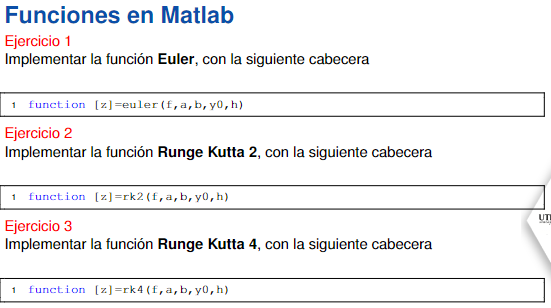

z = euler(f, 0, 1, 1, 0.1);


z =

     []




z = rk2(f,0,1,1,0.1);
f = @(t,y) (-y+t+2);
z = rk4(f,0,1,2,0.1)

ans = 2

z = 11×4 table
    ValorX    ValorY    AproxY    Diferencia
    ______    ______    ______    __________

       0           2         2             0
     0.1      2.0048    2.0048    8.1964e-08
     0.2      2.0187    2.0187    1.4833e-07
     0.3      2.0408    2.0408    2.0132e-07
     0.4      2.0703    2.0703    2.4288e-07
     0.5      2.1065    2.1065    2.7471e-07
     0.6      2.1488    2.1488    2.9828e-07
     0.7      2.1966    2.1966    3.1488e-07
     0.8      2.2493    2.2493    3.2562e-07
     0.9      2.3066    2.3066    3.3146e-07
       1      2.3679    2.3679    3.3324e-07


function [z] = rk4(f,a,b,y0,h)
    syms y(t) t
    y(t)=dsolve(diff(y,t)== f(t,y),y(0)==y0);
    SolEx=inline(subs(y(t)),'t');
    t=[a:h:b]';
    iteraciones = length(t);
    z = [];
    for i = 1:iteraciones
        z = [z;t(i) y0 SolEx(t(i)) abs(SolEx(t(i))-y0)];
        k1 = f(t(i), y0);
        k2 = f(t(i)+h/2, y0+(h/2)*k1);
        k3 = f(t(i)+h/2, y0+(h/2)*k2);
        k4 = f(t(i)+h, y0+k3*h);
        y0 = y0 + (h/6)*(k1+2*k2+2*k3+k4);
    end
    z = array2table(z,"VariableNames",["ValorX","ValorY","AproxY","Diferencia"]);
end
function [z] = rk2(f,a,b,y0,h)
    syms y(t) t
    y(t)=dsolve(diff(y,t)== f(t,y),y(0)==y0);
    SolEx=inline(subs(y(t)),'t');
    t=[a:h:b]';
    iteraciones = length(t);
    z = [];
    for i = 1:iteraciones
        z = [z;t(i) y0 SolEx(t(i)) abs(SolEx(t(i))-y0)];
        k1 = f(t(i), y0);
        k2 = f(t(i)+h, y0+h*k1);
        y0 = y0 + (h/2)*(k1+k2);
    end
    z = array2table(z,"VariableNames",["ValorX","ValorY","AproxY","Diferencia"]);
end
function [z] = euler(f,a,b,y0,h)
    syms y(t) t;
    y(t)=dsolve(diff(y,t)== f(t,y),y(0)==y0);
    SolEx=inline(subs(y(t)),'t');

    t = [a:h:b]';
    iteraciones = length(t);
    z = []
    %z = [t(1) y0 SolEx(t(1)) abs(SolEx(t(1))-y0)];
    for i = 1:iteraciones
        z = [z; t(i) y0 SolEx(t(i)) abs(SolEx(t(i))-y0)];
        y0 = y0 + h*f(t(i),y0);
    end
    z = array2table(z,"VariableNames",["ValorX","ValorY","AproxY","Diferencia"]);
end